# Loss function surface as a function of P_e and N

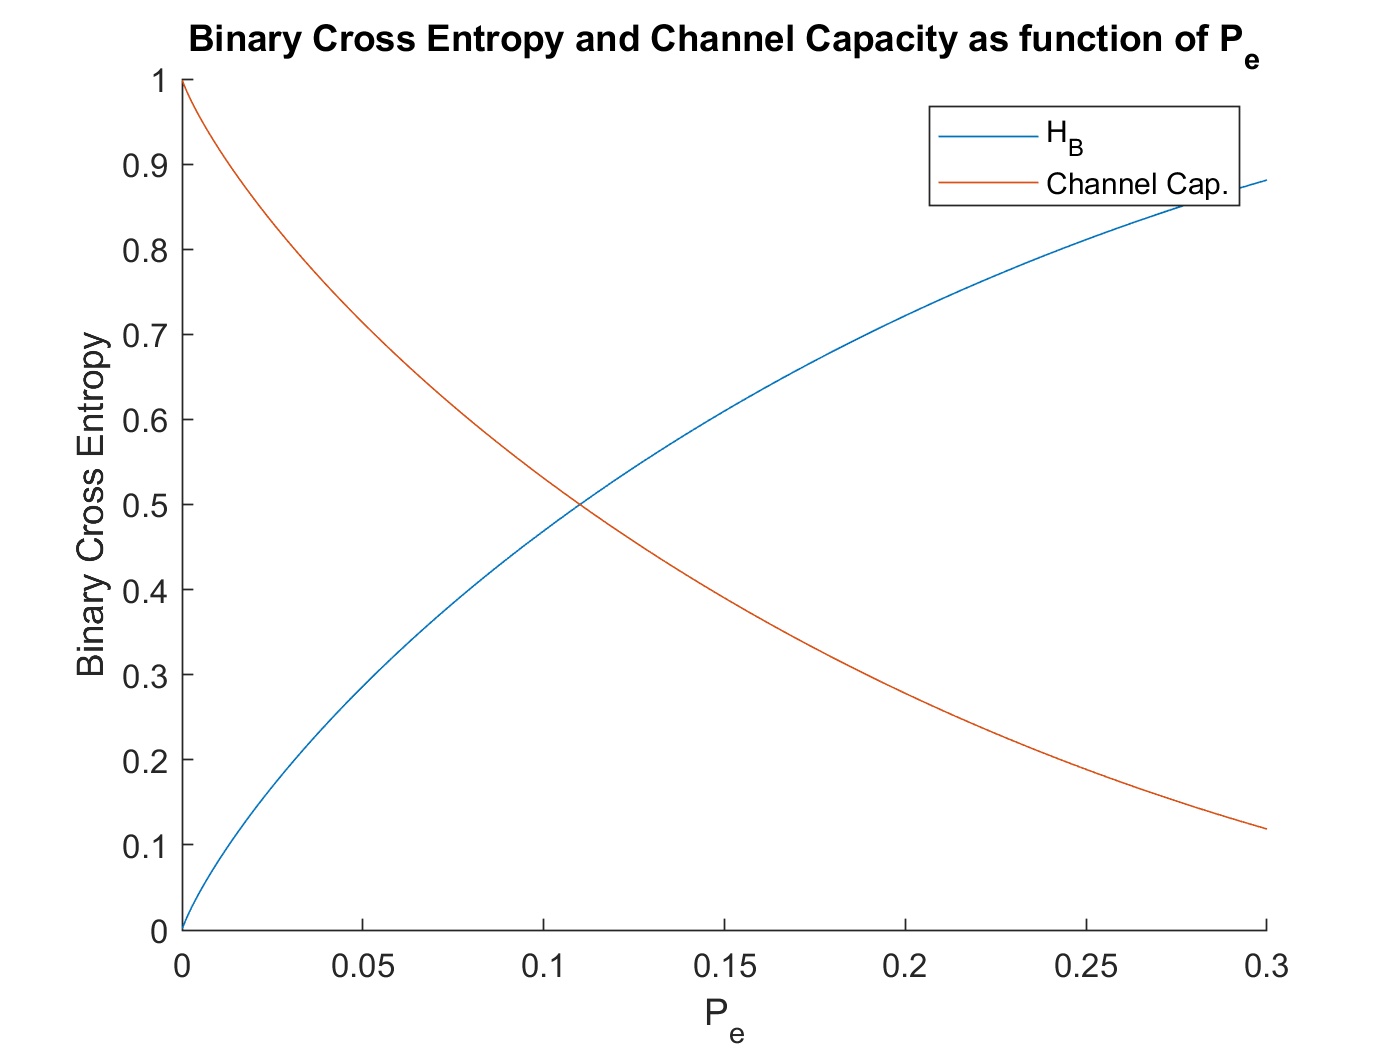

N = 100:100:10000;       %1x100
P_e = 10^-4:10^-4:0.3;  %1x3000

H_B = -(P_e.*log2(P_e) + (1-P_e).*log2(1-P_e));
figure;
hold on;
plot(P_e,H_B, "DisplayName", "H_B");
plot(P_e,1-H_B, "DisplayName", "Channel Cap.");
xlabel("P_e");
ylabel("Binary Cross Entropy");
title("Binary Cross Entropy and Channel Capacity as function of P_e");
legend;

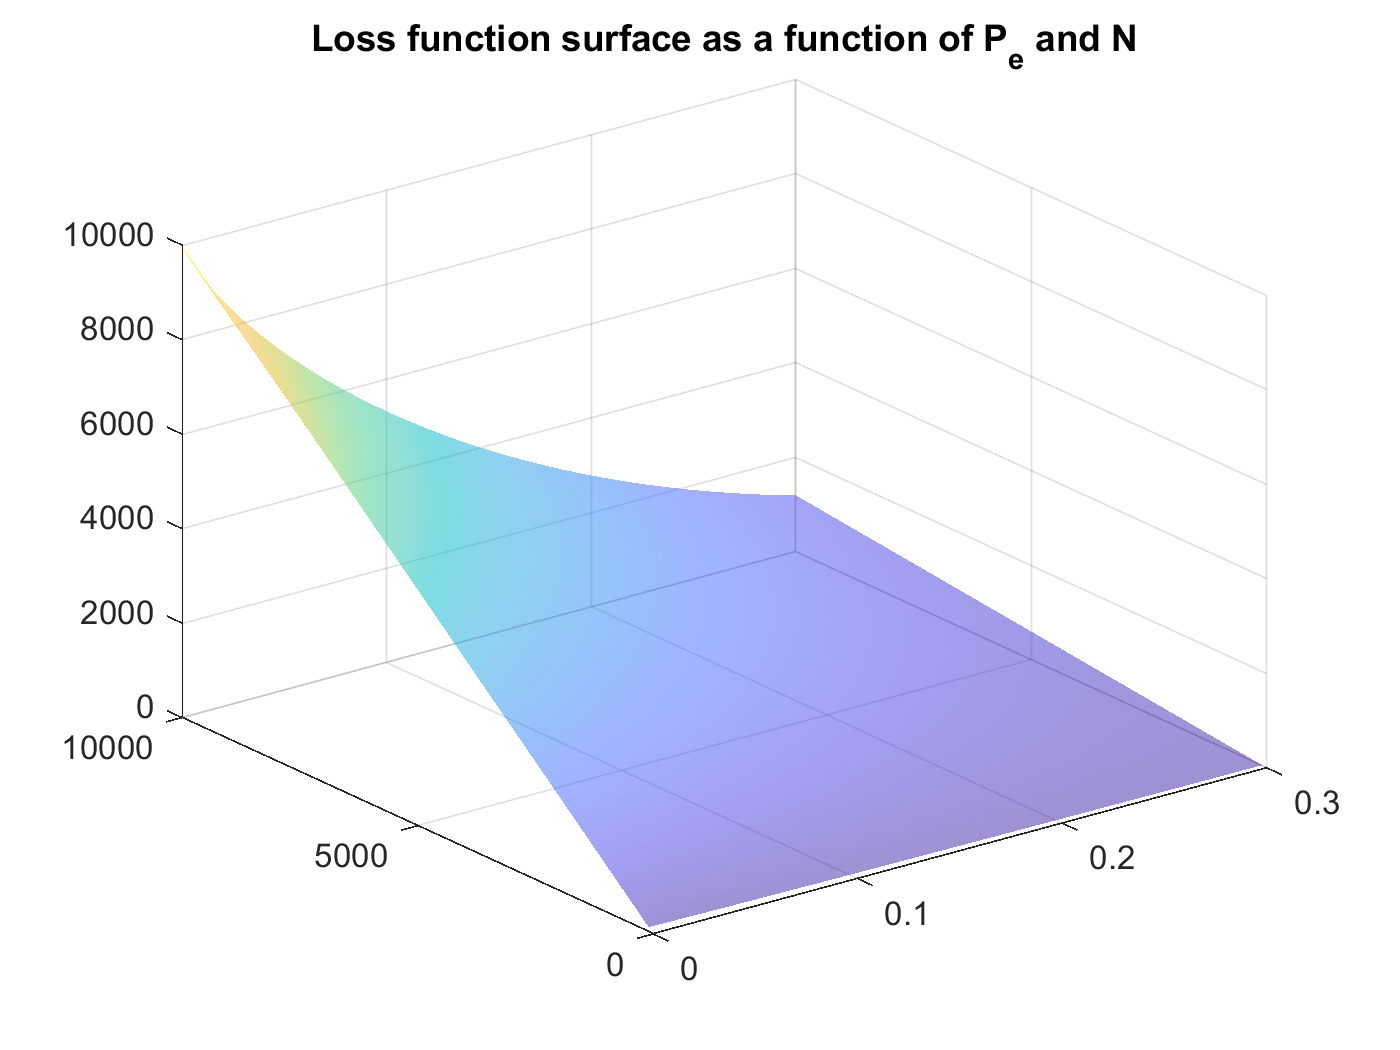


C = 1-H_B;
Theta = N'*C; %100x3000

figure;
% set(gca,'XScale','log');
% set(gca,'YScale','log');
surf(ones(100,1)*P_e, N'*ones(1,length(P_e)), Theta, 'FaceAlpha',0.5,'EdgeColor','none');
title("Loss function surface as a function of P_e and N");

# Histogram of signal points

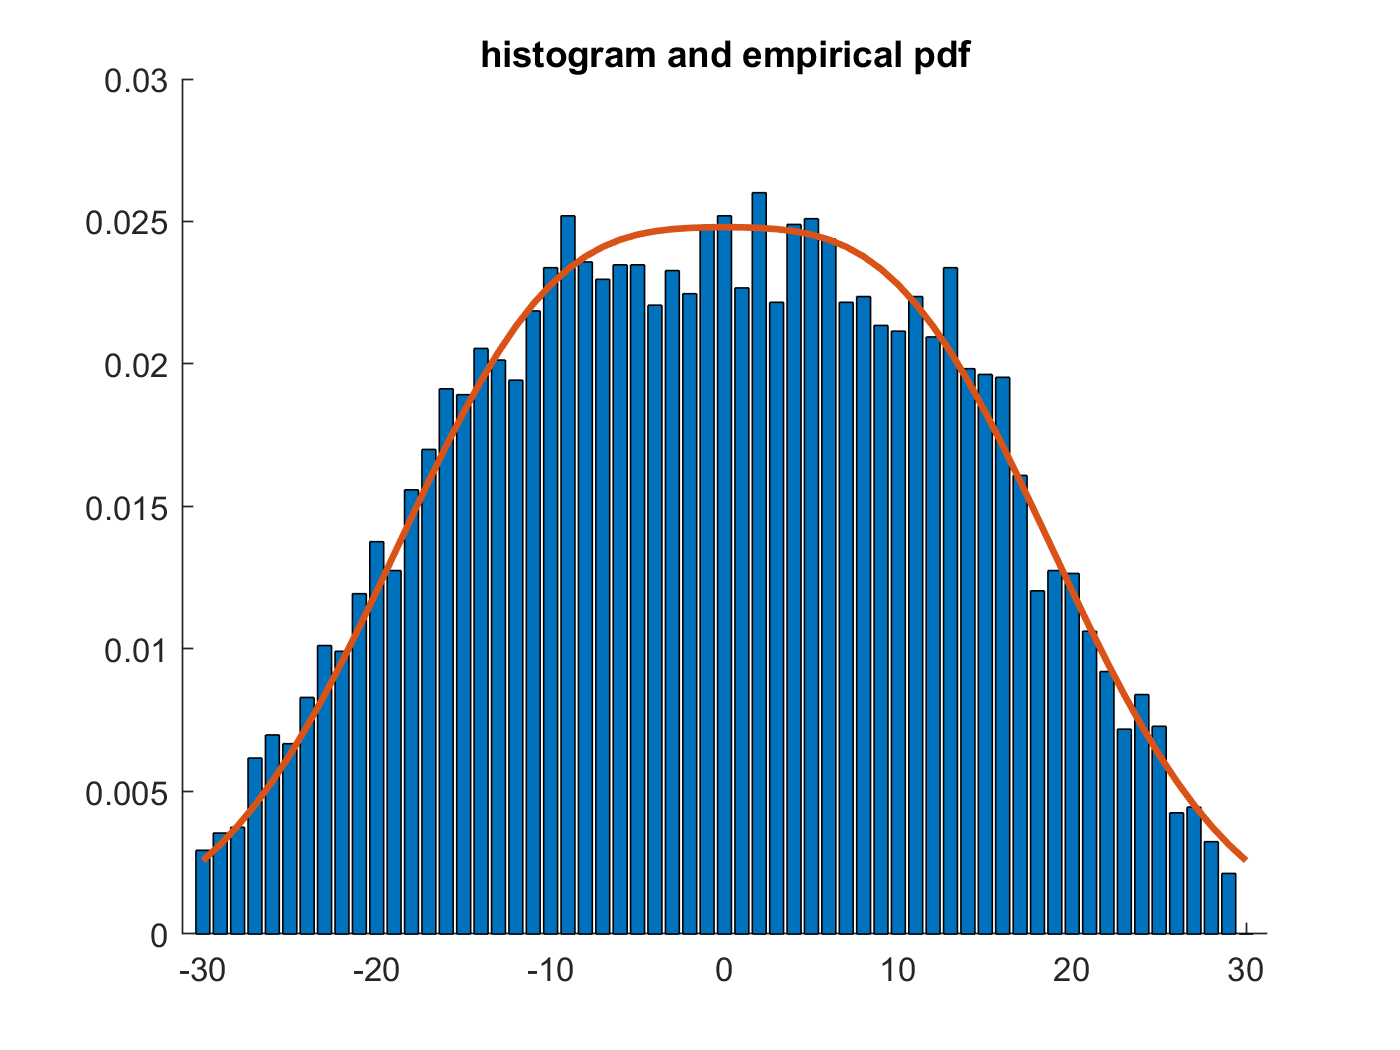

load data.mat data
energy = 9.75;
bins = -30:1:30;
sigma = 10;
data_hist = histc(data, bins)/length(data);
pdf = 0.5*(normpdf(bins, -energy, sigma)+normpdf(bins, energy, sigma));

% Plot histogram along with pdf
figure;
hold on;
title("histogram and empirical pdf");
bar(bins,data_hist);
plot(bins, pdf,"LineWidth",2); 

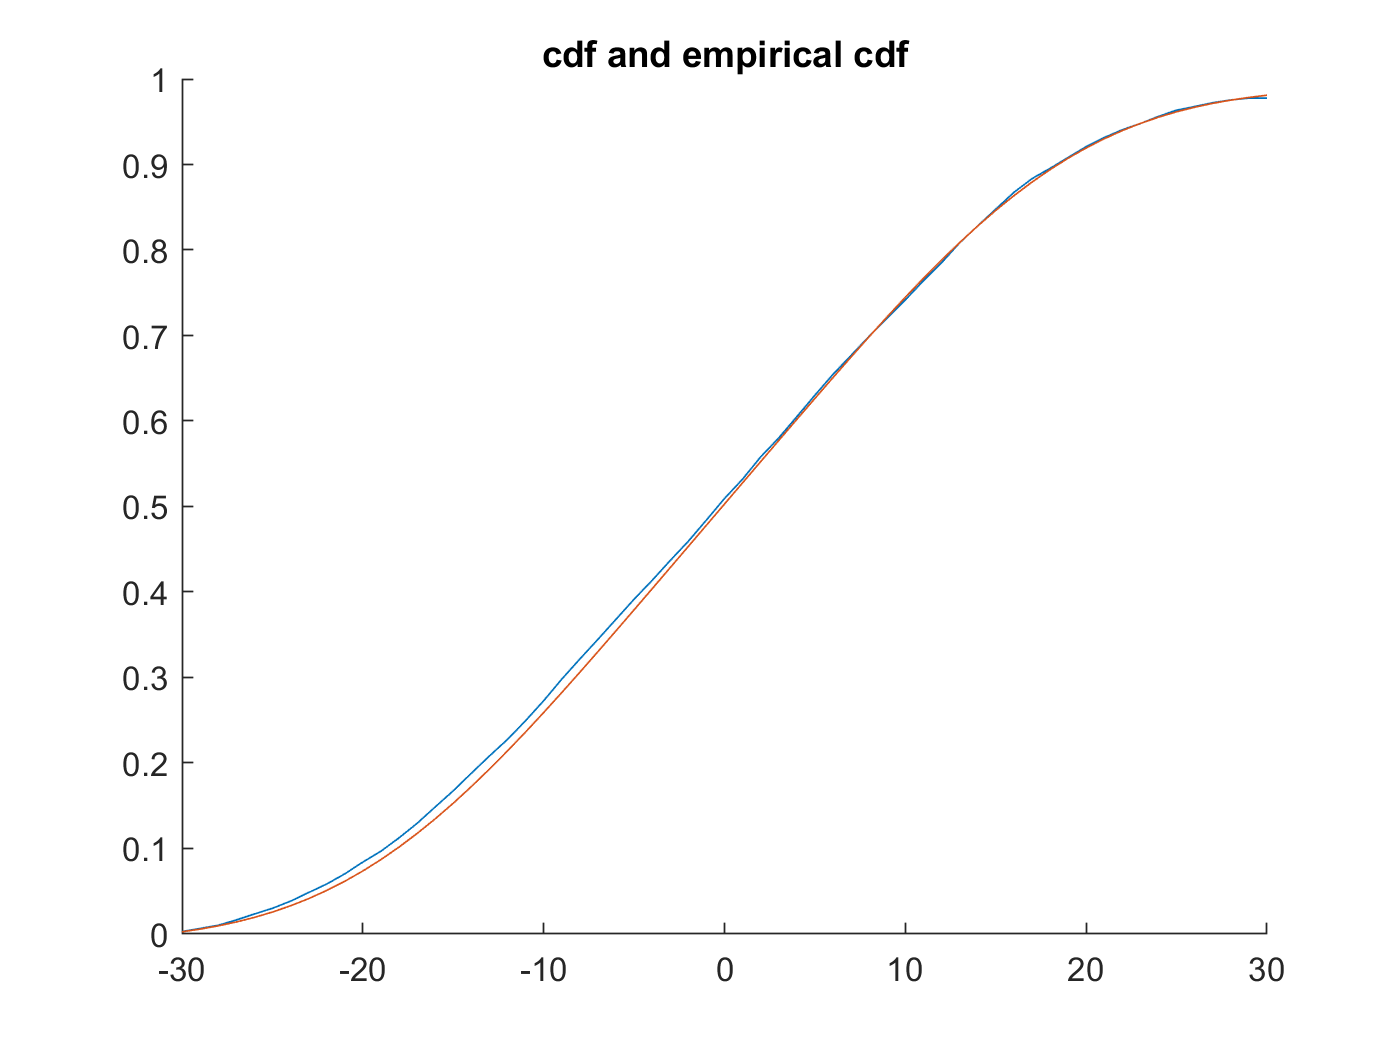


% Turn histogram into cumulative sum
empirical_cdf = zeros(1,length(bins));
cdf = zeros(1,length(bins));
for i=1:length(bins)
    empirical_cdf(i) = sum(data_hist(1:i));
    cdf(i) = sum(pdf(1:i));
end

figure;
hold on;
title("cdf and empirical cdf");
plot(bins, empirical_cdf);
plot(bins, cdf);

# [Empirical parameter tuning] P_e vs. N for Scheme 3

N_target = [2000 4000 6000 8000 10000];
N_correct = [1995 3882 5607 7150 8720];
scores = [2748 3428 3610 3826 3997]

scores =         2748        3428        3610        3826        3997


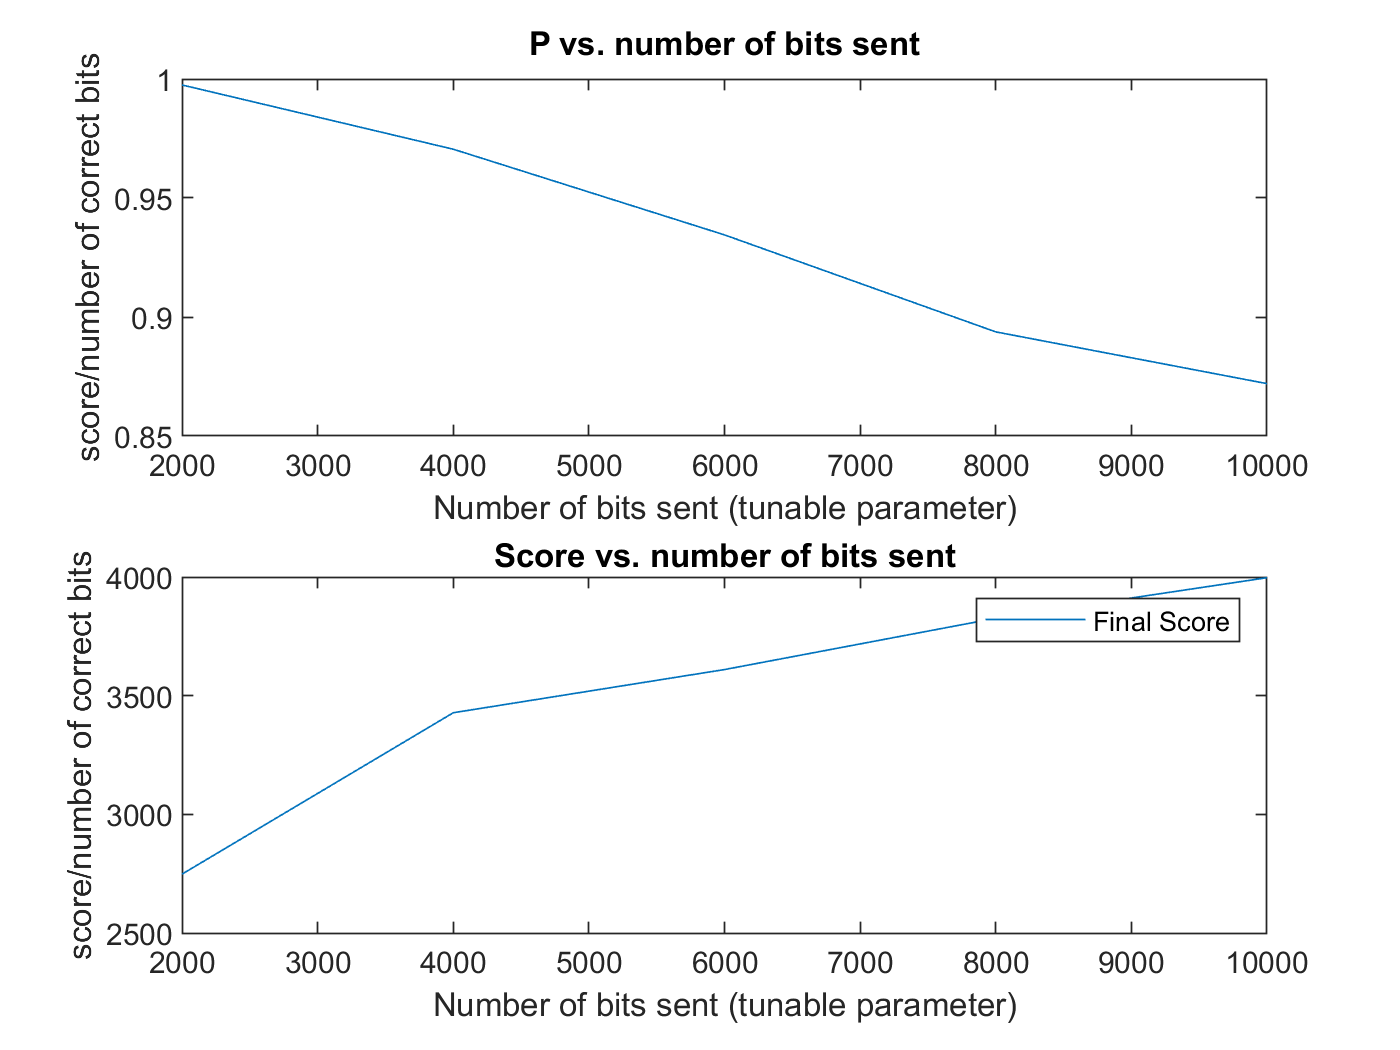


% Other parameters (only for documentation, do not participate in calculations)
safety_margin = 0.95;
P_resend = 0.3;

P_e = N_correct./N_target;

figure;
subplot(2,1,1);
plot(N_target, P_e);
title("P_ vs. number of bits sent");
xlabel("Number of bits sent (tunable parameter)");
ylabel("score/number of correct bits")
subplot(2,1,2);
plot(N_target, scores, "DisplayName", "Final Score");
% plot(N_target, N_correct, "DisplayName", "Correct bits");
legend;
title("Score vs. number of bits sent");
xlabel("Number of bits sent (tunable parameter)");
ylabel("score/number of correct bits")

# [Empirical parameter tuning] P_e vs. resend_threshold for Scheme 3

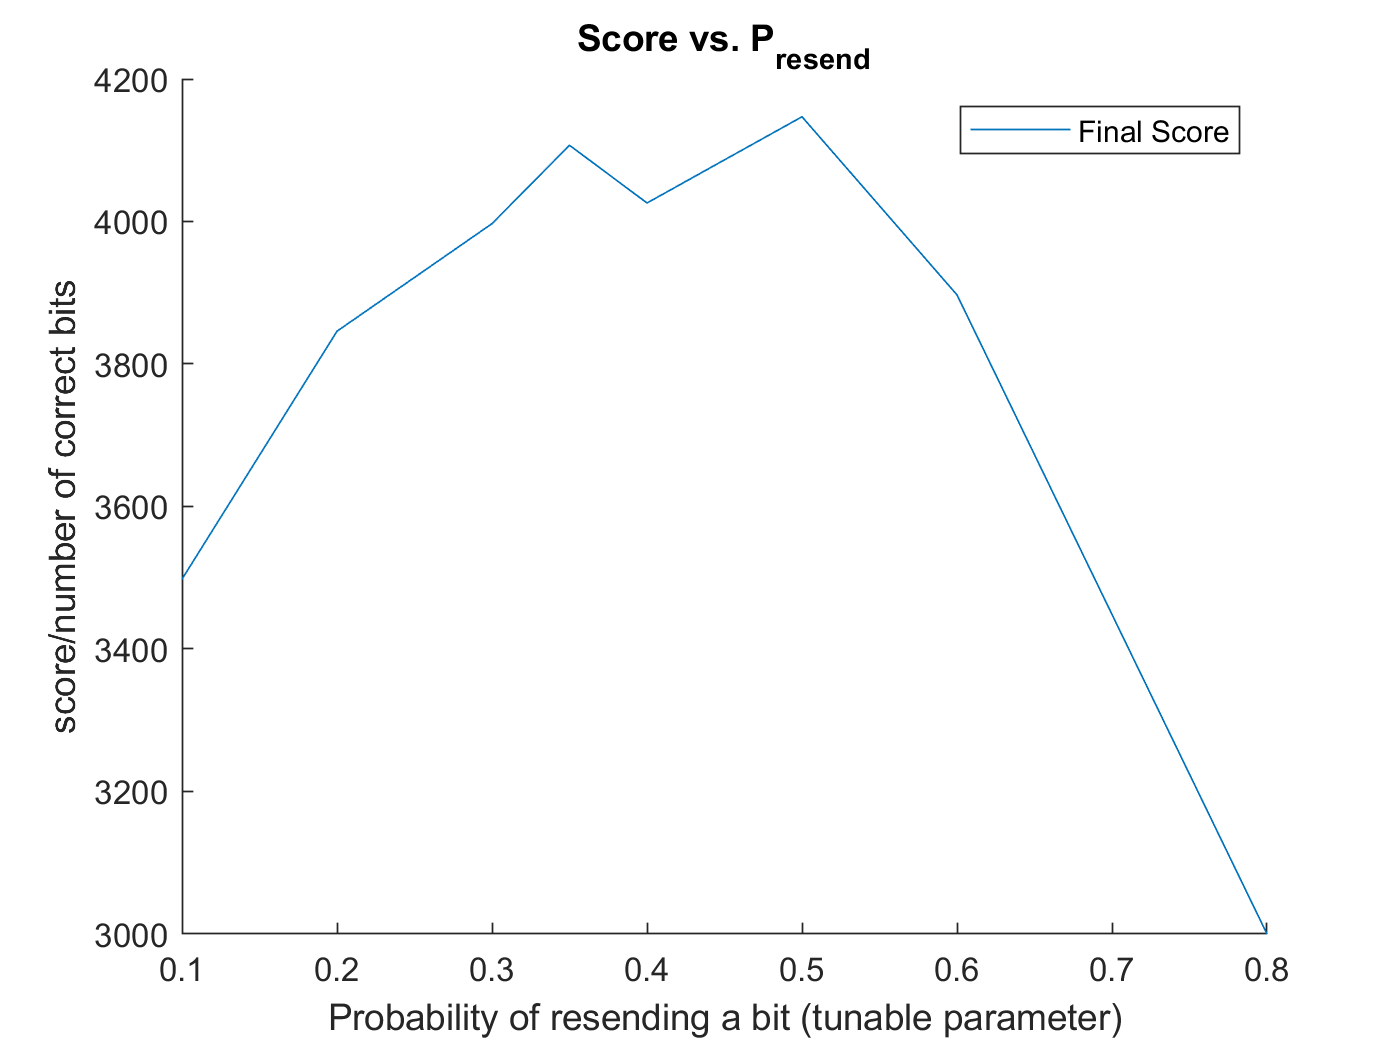

N_target = 10000;
N_correct = [8531 8665 8720 8760 8731 8773 8681 8322];
P_resend = [0.1 0.2 0.3 0.35 0.4 0.5 0.6 0.8];
scores = [3498 3846 3997 4107 4026 4147 3897 3000];

figure;
hold on;
plot(P_resend, scores, "DisplayName", "Final Score");
% plot(P_resend, N_correct, "DisplayName", "Correct bits");
legend;
title("Score vs. P_{resend}");
xlabel("Probability of resending a bit (tunable parameter)");
ylabel("score/number of correct bits")

# [Empirical parameter tuning] P_e vs. carrier frequency for Scheme 5

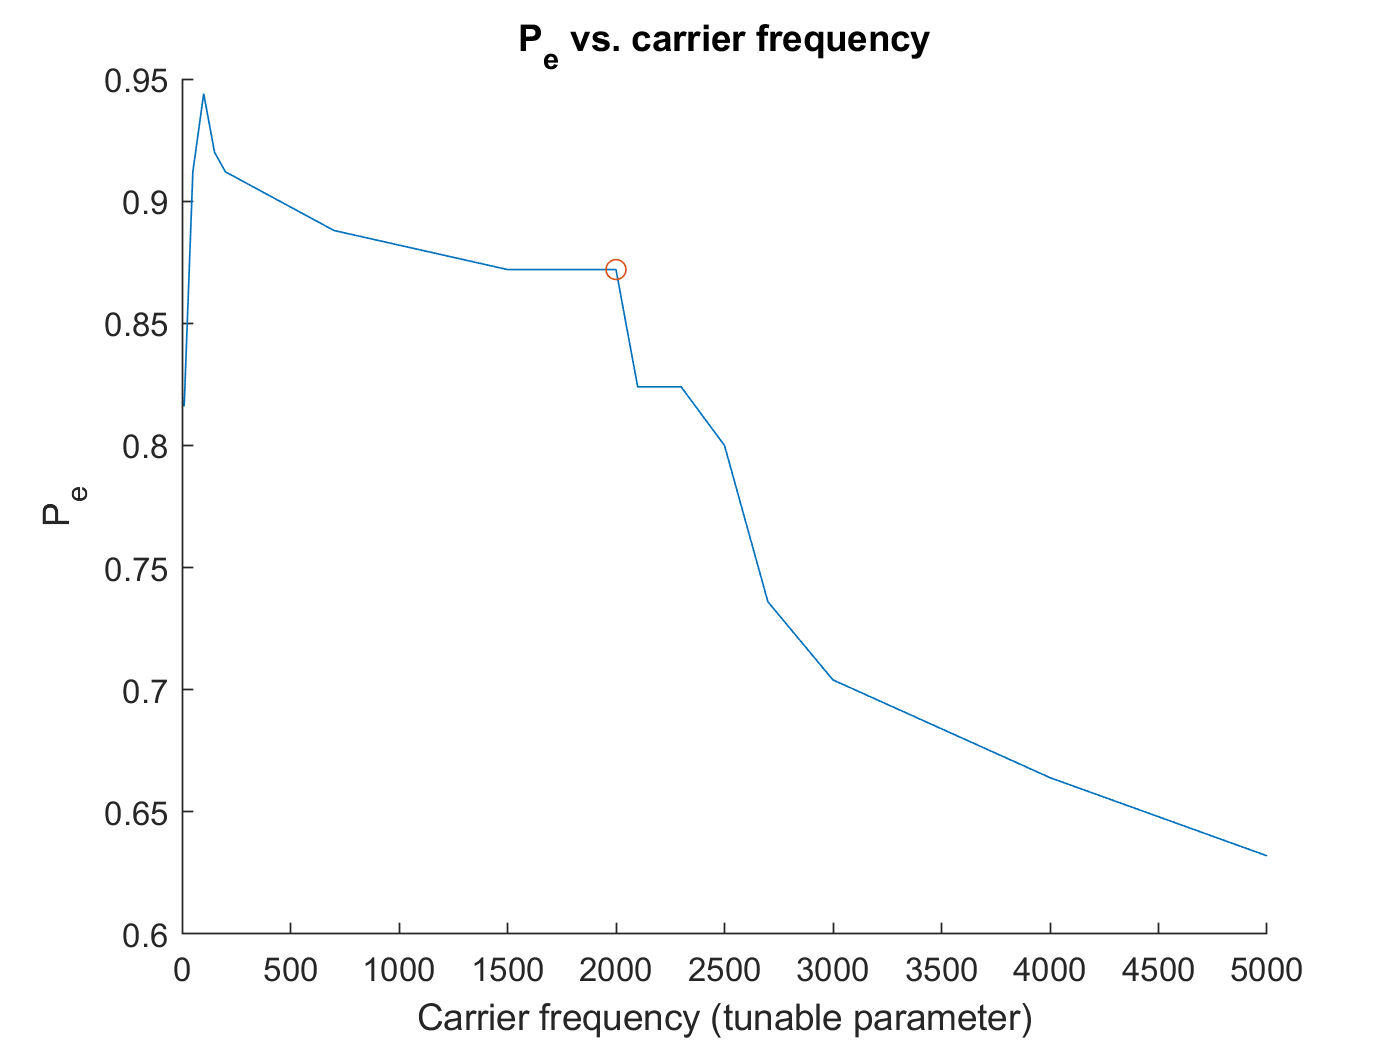

N_target = 125;
N_correct = [102 114 118 115 114 111 109 109 103 103 100 92 88 83 79];
freq = [10 50 100 150 200 700 1500 2000 2100 2300 2500 2700 3000 4000 5000];


P_e = N_correct./N_target;
figure;
hold on;
plot(freq, P_e, "DisplayName", "prob. of error");
scatter(2000,0.872);
title("P_e vs. carrier frequency");
xlabel("Carrier frequency (tunable parameter)");
ylabel("P_e")